% opMichC1.m

clear
clc
close all

wL(1) = 600e-9;
wL(2) = 600e-9;

z1 = 0;

Amax = 5;
zp = 0.200;
xpMax = zp*tand(Amax);
%z2 = 1.27

z2 = -1.3e-3; %1014*wL(1);


nP = 199;
xp = linspace(-xpMax,xpMax,nP);

k = 2*pi./wL;


phi(1) = 0;
phi(2) = pi;

R1 = sqrt(zp^2      + xp.^2);
R2 = sqrt((zp-z2)^2 + xp.^2);

% delta = 2*(1.5-1)*1e-3;
% R1 = R1+delta;

E1 = zeros(2,nP);
E2 = zeros(2,nP);
E = zeros(1,nP);

for cn = 1 : 2
  E1(cn,:) = fun(k(1),R1,phi(1));
  E2(cn,:) = fun(k(2),R2,phi(2));
  E = E + E1(cn,:) + E2(cn,:);
end



intensity = E.*conj(E);


mMAX = 2*z2/wL(1)

mMAX = -4.3333e+03

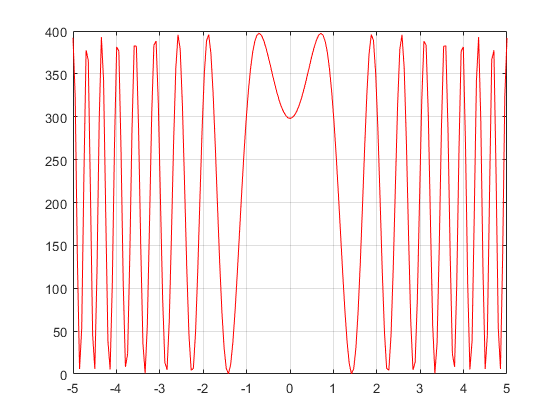




figure(1)
%xP = xp;
xP = atand(xp./zp);
yP = intensity;
plot(xP,yP,'r')
%ylim([-0.1 1.1])
grid on

function E = fun(k,R,phi)
  E = exp(1i*k*R + 1i*phi)./R;
end